## Figure 2 

clear all; close all; clc;

%add the source data
addpath 'path\to\data_source';
addpath 'path\to\INTHIS\DataAnalysis';

%load 
load S.mat;

## Get the data

%get the indentation
Sn="S6";
Tn="T16";

%get the spike data
fbgs=S.(Sn).(Tn).FBGs;
neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
roi=S.(Sn).(Tn).ROI;
ind=S.(Sn).(Tn).Ind;

%threshold the fbgs
fbgs(:,2:end)=fbgs(:,2:end)-fbgs(1,2:end);
tmin=min(neurons(:,1))-1;
limits=[0 max(neurons(:,1))+1-tmin];

%compute the firing rates
neuronsFR=computeFR(neurons,900);
motorsFR=computeFR(motors,23);

## sub1

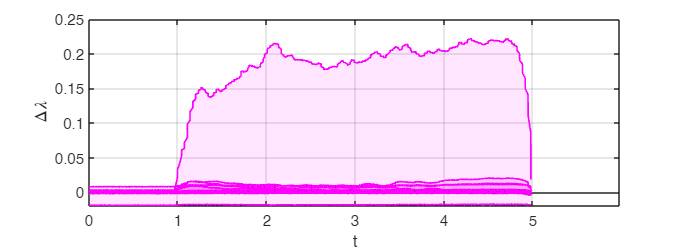

sub1=figure('Units','centimeters','Position',[2.4 1 14.5 5.3]);

data=fbgs; hold on; grid on; box on;
n=7;
c=flipud(slanCM('plasma',n));
for i=1:21
    % if i==21
    %     continue;
    % end
    x=data(:,1)-tmin;
    y=data(:,i+1);
    area(x,y,'FaceAlpha',0.1,'FaceColor','m'); 
    plot(x,y,'LineWidth',1,'Color','m');
    [val,ix]=max(y);
    % text(x(ix),val,sprintf('%d',i));
end
%legend()
xlim(limits); ylim([-0.02 0.25]);
xlabel('t'); ylabel('\Delta\lambda'); hold off;


%export
% saveas(sub1,'subfigures/sub1.fig');
% exportgraphics(sub1, 'subfigures/sub1.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub1, 'subfigures/sub1.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Sub2

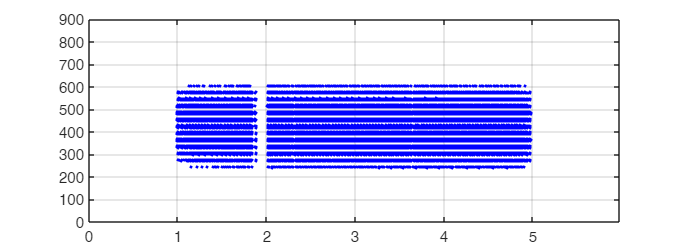

%create figure
sub2=figure('Units','centimeters','Position',[2.4 1 14.5 5.3]);
data=neurons; scatter(data(:,1)-tmin,data(:,2),3,'filled','b'); grid on; xlim(limits); ylim([0 900]); yticks(0:100:901); box on;

%export
% saveas(sub2,'subfigures/sub2.fig');
% exportgraphics(sub2, 'subfigures/sub2.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub2, 'subfigures/sub2.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Sub3

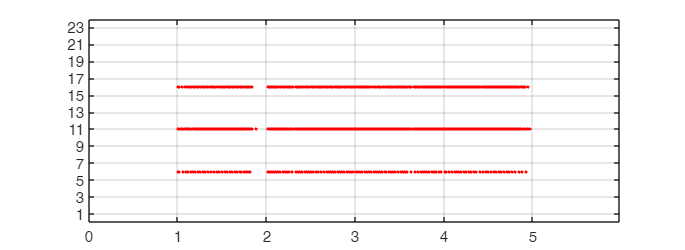

sub3=figure('Units','centimeters','Position',[2.4 1 14.5 5.3]);
data=motors; hold on; yticks(1:2:23); grid on; scatter(data(:,1)-tmin,data(:,2),3,'filled','r'); hold off; xlim(limits); ylim([0 24]); box on;

%export
% saveas(sub3,'subfigures/sub3.fig');
% exportgraphics(sub3, 'subfigures/sub3.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub3, 'subfigures/sub3.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Sub4

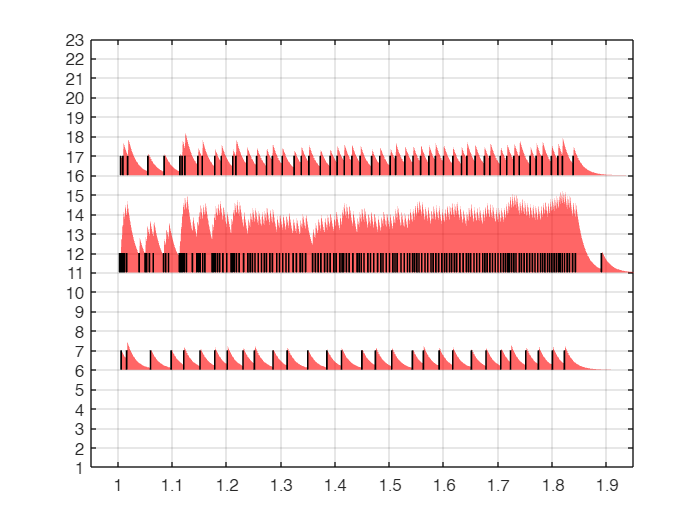

C=colororder;
% motors(motors(:,2)==6,2)=4;
% motors=motors(find(or(motors(:,2)==1,motors(:,2)==2)),:);
% motors(:,2)=motors(:,2)*2;
motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
motors(:,1)=motors(:,1)-tmin;

%timing issues
tc=0.001; %s
tau=0.015; %s
g=15;
a=tc/(tau+tc);
T=6; %s
N=T/tc;
t0=motors(1,1);
time=(0:tc:T)'; time(end)=[]; %ms


%extract and process data
ids=motors(:,2);
allspikes=motors(:,1); 

sub4=figure(); hold on;

%xline
% xtresh=2;
% xline(xtresh,'LineWidth',1,'Color','k');

grid on; 

%create the 23 signals
for i=1:23 %4

    %compute spiketimes
    spiketimes=motors(motors(:,2)==i,1);

    %signals containers
    y=zeros(N,1);
    x=zeros(N,1);
    [~,closestIndex] = min(abs(time-spiketimes'));
    x(closestIndex)=1;

    %filtering operation
    for n=1:(N-1)    
        y(n+1)=g*a*x(n)+(1-a)*y(n);
    end

    %result
    % ix=time<xtresh;
    % time=time(ix);
    % y=y(ix);
    % y(1)=0; y(end)=0;
    %fill(time(:),y(:),0,'FaceColor',C(i,:),'FaceAlpha',0.4);
    if any(y)
        % plot(time,y+i,'Color','r');
        fill(time,y+i,0,'FaceColor','r','FaceAlpha',0.6,'EdgeColor','none');
    end
end


% %plot all the spikes as lines
for i=1:length(ids)
    if 1
        line([allspikes(i) allspikes(i)], [ids(i) ids(i)+1],'Linewidth',1,'Color','k');
    end
end

% % set(gca, 'XDir','reverse');
% %set(gca,'YTickLabel',[]);
yticks(1:1:23);
ylim([1 23]);
xlim([0.95 1.95]);
box on;
hold off;  %xlim([0 1000]); box on;  ylim([1.5 6]);

%export
% saveas(sub4,'subfigures/sub4.fig');
% exportgraphics(sub4, 'subfigures/sub4.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub4, 'subfigures/sub4.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Load meshes and data

%select 
%FBG Skin DOMAIN
load FBG_x.csv;
load FBG_y.csv;
load FBG_z.csv;

%FBG Skin DOMAIN
load xi.csv;
load yi.csv;
load zi.csv;

%load NN structure

%get sensorspositions
load sx.csv;
load sy.csv;
load sz.csv;

%get neuronspositions
load xc.csv
load yc.csv;
load zc.csv;
Tri = delaunay(xc,yc);

%get motorpositions
load xm.csv
load ym.csv;
load zm.csv;

%read stl of sensors line
importstl=stlread("path_fbg.stl");

%load deltas
load deltax.mat
load deltay.mat
load deltaz.mat

%compute lines
linex=-importstl.Points(:,1)+deltax;
liney=importstl.Points(:,3)+deltay;
linez=importstl.Points(:,2)+deltaz;

load Wh.csv
load Wh2.csv

## Sub5

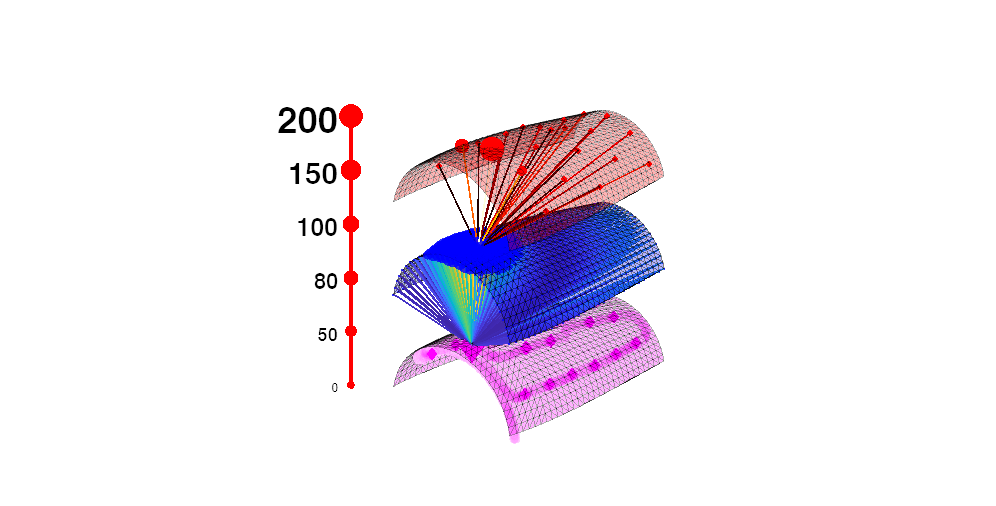

sub5=figure('Units','centimeters','Position',[5.2,2.1,31.5,16]); hold on;
delta=60;

%neurons
trisurf(Tri, xc, yc, zc,Wh(11,:),'EdgeAlpha',0.5,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','b');
scatter3(xc,yc,zc,neuronsFR+1,'b','filled','markerFaceAlpha',0.8,'MarkerEdgeColor','none');

%sensors
scatter3(linex,liney,linez-delta,30,"MarkerFaceColor",'m',"MarkerFaceAlpha",0.03,"MarkerEdgeColor","none");
trisurf(Tri, xc, yc, zc-delta,'EdgeAlpha',0.3,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','m');
scatter3(sx,sy,sz-delta,rescale(max(fbgs(:,2:end)),30,200),'dm','filled','markerFaceAlpha',1,'MarkerEdgeColor','none'); 
% scatter3(sx(11),sy(11),sz(11)-delta,80,'db','filled','markerFaceAlpha',1,'MarkerEdgeColor','k'); 
% for i=1:length(sx)
%     text(sx(i),sy(i),sz(i)-delta+5,sprintf('%d',i),'Color','k','FontWeight','bold','FontSize',6);
% end

%motors
motorsFR(motorsFR==0)=20;
scatter3(xm,ym,zm+delta,motorsFR,'or','filled','AlphaData',0.7,'MarkerEdgeColor','none');
trisurf(Tri, xc, yc, zc+delta,'EdgeAlpha',0.3,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','r');
% for i=1:length(xm)
%     text(xm(i),ym(i),zm(i)+delta+5,sprintf('%d',i),'Color','k','FontWeight','bold','FontSize',6);
% end

%lines
strengths2=rescale(Wh2(:,455),1,23);
cmap2=hot(23);
ref=[xc(455) yc(455) zc(455)];
for n=1:length(xm)
    pt=[xm(n) ym(n) zm(n)+delta];
    ix=floor(strengths2(n));
    xyz=vertcat(ref,pt);
    p=plot3(xyz(:,1),xyz(:,2),xyz(:,3),'LineWidth',1,'Color',cmap2(ix,:));
end

%lines
% strengths2=rescale(Wh2(:,475),1,23);
% cmap2=hot(23);
% ref=[xc(475) yc(475) zc(475)];
% for n=1:length(xm)
%     pt=[xm(n) ym(n) zm(n)+delta];
%     ix=floor(strengths2(n));
%     xyz=vertcat(ref,pt);
%     plot3(xyz(:,1),xyz(:,2),xyz(:,3),'LineWidth',1,'Color',cmap2(ix,:));
% end

%lines
strengths=rescale(Wh(11,:),1,900);
cmap=parula(900);
ref=[sx(11) sy(11) sz(11)-delta];
for n=1:length(xc)
    pt=[xc(n) yc(n) zc(n)];
    ix=floor(strengths(n));
    xyz=vertcat(ref,pt);
    plot3(xyz(:,1),xyz(:,2),xyz(:,3),'LineWidth',1,'Color',cmap(ix,:));
end

%redscale
xpos=-70;
ypos=-10;
scaleFR=[20 50 80 100 150 200];
scalex=xpos*ones(1,length(scaleFR));
scaley=ypos*ones(1,length(scaleFR));
scalez=35*((1:length(scaleFR))-1)-50;
plot3([xpos xpos],[ypos ypos],[min(scalez) max(scalez)],'LineWidth',2,'Color','r');
scatter3(scalex,scaley,scalez,scaleFR+1,'or','filled');
scaleFR(1)=0;
for i=1:length(scalex)
    size=ceil(scaleFR(i)/14)+7;
    text(scalex(i)-3,scaley(i)-8,scalez(i),sprintf('%d',scaleFR(i)),'Color','k','FontSize',size,'FontWeight','bold','VerticalAlignment', 'middle','HorizontalAlignment', 'right');
end

hold off; view(45,25); axis equal; axis off;
%export
saveas(sub5,'subfigures/sub5new3.fig');
exportgraphics(sub5, 'subfigures/sub5new3.png', 'ContentType', 'image','Resolution',300);
exportgraphics(sub5, 'subfigures/sub5new3.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Sub6

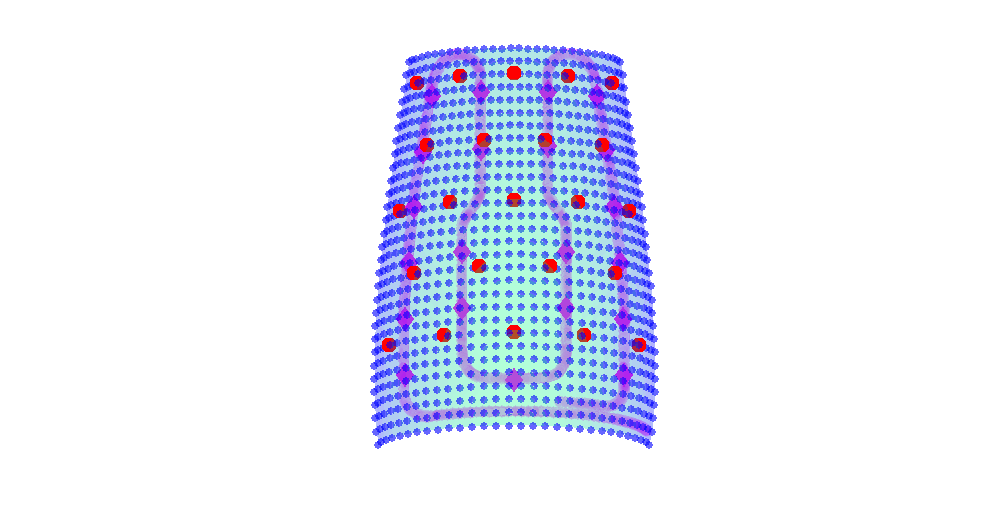

sub6=figure('Units','centimeters','Position',[5.2,2.1,31.5,16]);
hold on;

%neurons
trisurf(Tri, xc, yc, zc,'EdgeAlpha',0.5,'EdgeColor','none','FaceAlpha',0.3); colormap winter;
scatter3(xc,yc,zc,20,'b','filled','markerFaceAlpha',0.6,'MarkerEdgeColor','none');

%sensors
scatter3(linex,liney,linez,30,"MarkerFaceColor",'m',"MarkerFaceAlpha",0.05,"MarkerEdgeColor","none");
%trisurf(Tri, xc, yc, zc-delta,'EdgeAlpha',0.3,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','m');
scatter3(sx,sy,sz,100,'dm','filled','markerFaceAlpha',1,'MarkerEdgeColor','none'); 
% scatter3(sx(11),sy(11),sz(11)-delta,80,'db','filled','markerFaceAlpha',1,'MarkerEdgeColor','k'); 
% for i=1:length(sx)
%     text(sx(i),sy(i),sz(i)+5,sprintf('%d',i),'Color','k','FontWeight','bold','FontSize',6);
% end

%motors
scatter3(xm,ym,zm,80,'or','filled','AlphaData',0.7,'MarkerEdgeColor','none');
%trisurf(Tri, xc, yc, zc+delta,'EdgeAlpha',0.3,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','r');
% for i=1:length(xm)
%     text(xm(i),ym(i),zm(i)+5,sprintf('%d',i),'Color','k','FontWeight','bold','FontSize',6);
% end

hold off; view(0,80); axis equal; axis off;

%export
% saveas(sub6,'subfigures/sub6.fig');
% exportgraphics(sub6, 'subfigures/sub6.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub6, 'subfigures/sub6.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Sub7

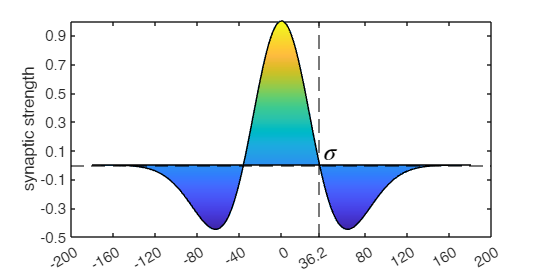

sub7=figure('Units','centimeters','Position',[2,0.8,11.5,5.8]);

hold on;

x=linspace(-180,180,1000); sigma=36.2;
m=(1-(x/sigma).^2).*exp((-x.^2)/(2*sigma^2));
m=m/max(m);
m(1)=0;

hold on;
plot(x,m,'LineWidth',1);
xline(sigma,'k--');
yline(0,'k--');
ylabel('synaptic strength');
ticks=-200:40:200; ticks(ticks==40)=[];
xticks(sort([ticks sigma]));
yticks(-0.5:0.2:1);
text(sigma+1,0.1,'\sigma','FontSize',15);
box on;
patch(x,m,m); colormap parula;
hold off;

%export
% saveas(sub7,'subfigures/sub7.fig');
% exportgraphics(sub7, 'subfigures/sub7.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub7, 'subfigures/sub7.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Sub8

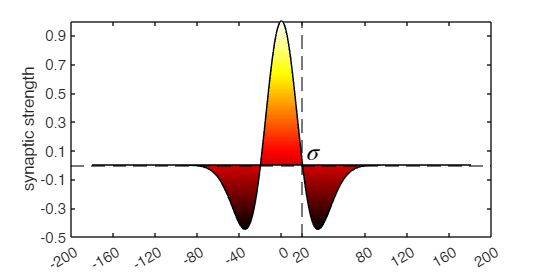

sub8=figure('Units','centimeters','Position',[2,0.8,11.5,5.8]);

hold on;

x=linspace(-180,180,1000); sigma=20;
m=(1-(x/sigma).^2).*exp((-x.^2)/(2*sigma^2));
m=m/max(m);
m(1)=0;

hold on;
plot(x,m,'LineWidth',1);
xline(sigma,'k--');
yline(0,'k--');
ylabel('synaptic strength');
ticks=-200:40:200; ticks(ticks==40)=[];
xticks(sort([ticks sigma]));
yticks(-0.5:0.2:1);
text(sigma+1,0.1,'\sigma','FontSize',15);
box on;
patch(x,m,m); colormap hot;
hold off;

%export
% saveas(sub8,'subfigures/sub8.fig');
% exportgraphics(sub8, 'subfigures/sub8.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub8, 'subfigures/sub8.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);